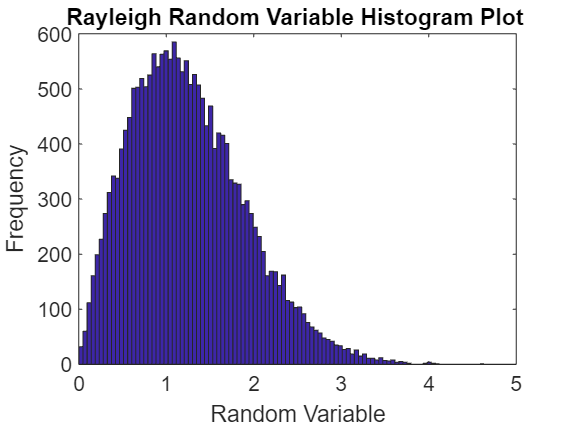

clc;
clear;
N=20000;
SNR_limit = 35;
SNR_db=-35:0.5:SNR_limit;
SNR=10.^(SNR_db/10);
u=rand(1,N);
var=1;
p=SNR*var;


r=sqrt(-(2*var*log(u)));
figure(1);
hist(r,100);
title("Rayleigh Random Variable Histogram Plot ")
xlabel("Random Variable")
ylabel("Frequency")

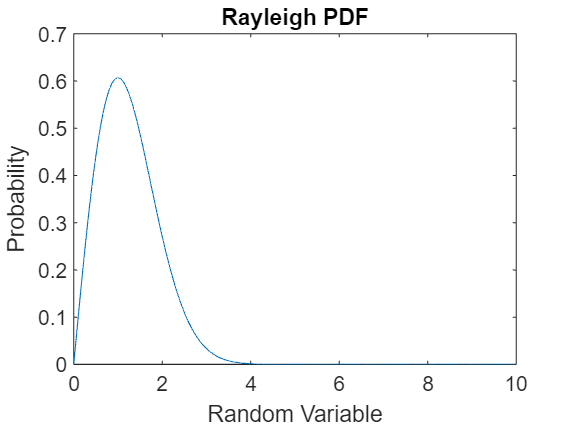


a=0:0.01:10;
R=(a/var).*exp(-(a.*a)/(2*var));
figure(2);
plot(a,R);
title("Rayleigh PDF")
xlabel("Random Variable")
ylabel("Probability")

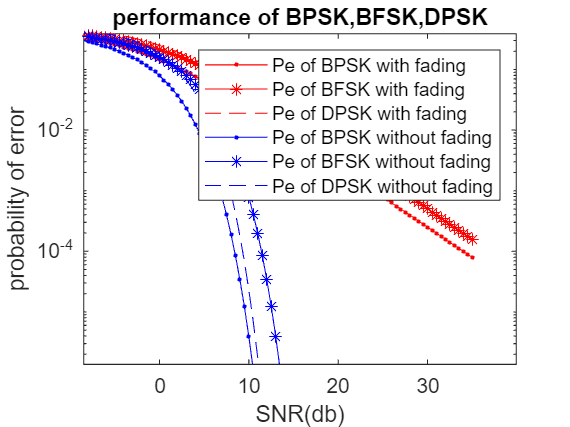


% with fading
pe_bpsk_f=0.5*(1-sqrt(p./(1+p)));

pe_bfsk_f=0.5*(1-sqrt(p./(2+p)));

pe_dpsk_f=(0.5)./(1+p);

% No fading
pe_bpsk_nf=0.5*erfc(sqrt(SNR));
pe_bfsk_nf=0.5*erfc(sqrt(SNR/2));
pe_dpsk_nf=0.5*exp(-SNR);

figure(3);
semilogy(SNR_db,pe_bpsk_f,'r.-', SNR_db,pe_bfsk_f,'r*-',SNR_db,pe_dpsk_f,'r--', SNR_db,pe_bpsk_nf,'b.-',SNR_db,pe_bfsk_nf,'b*-',SNR_db,pe_dpsk_nf,'b--');
axis([-5 SNR_limit 0.000001 1]);
title('performance of BPSK,BFSK,DPSK')
xlabel('SNR(db)');
ylabel('probability of error');
legend('Pe of BPSK with fading','Pe of BFSK with fading','Pe of DPSK with fading','Pe of BPSK without fading','Pe of BFSK without fading','Pe of DPSK without fading');